## divide train set and test set

[~, band1] = min(abs(effshift - 477));
[~, band2] = min(abs(effshift - 1593));
[~, band3] = min(abs(effshift - 1627));
band = [band1, band2, band3]

data = X(:, band);
label = y;

band =     20   324   334


% ratio = 0.75;
% num_train = floor(length(label)*ratio); 
% choose = randperm(length(label)); 

train_data  = data(choose(1:num_train), :);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), :);
test_label  = label(choose(num_train+1:end));

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);
toc

*
optimization finished, #iter = 69
nu = 1.000000
obj = -8.614742, rho = 0.005603
nSV = 138, nBSV = 138
*
optimization finished, #iter = 70
nu = 0.992806
obj = -8.555399, rho = 0.974878
nSV = 138, nBSV = 138
*
optimization finished, #iter = 65
nu = 0.962406
obj = -7.977583, rho = -0.988351
nSV = 128, nBSV = 128
*
optimization finished, #iter = 69
nu = 0.992806
obj = -8.560747, rho = 0.976448
nSV = 138, nBSV = 138
*
optimization finished, #iter = 64
nu = 0.962406
obj = -7.970896, rho = -0.989114
nSV = 128, nBSV = 128
*
optimization finished, #iter = 64
nu = 0.955224
obj = -7.991704, rho = -0.994971
nSV = 128, nBSV = 128
Total nSV = 271
*
optimization finished, #iter = 68
nu = 1.000000
obj = -8.488187, rho = 0.005452
nSV = 136, nBSV = 136
*
optimization finished, #iter = 69
nu = 0.992701
obj = -8.431548, rho = 0.974990
nSV = 136, nBSV = 136
*
optimization finished, #iter = 65
nu = 0.969697
obj = -7.977048, rho = -0.987480
nSV = 128, nBSV = 128
*
optimization finished, #iter = 69
nu = 0.9

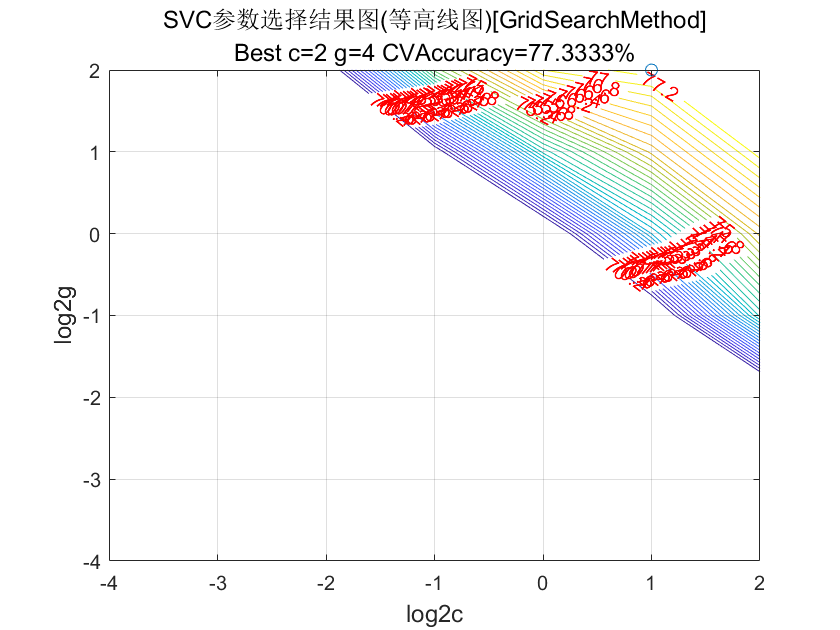

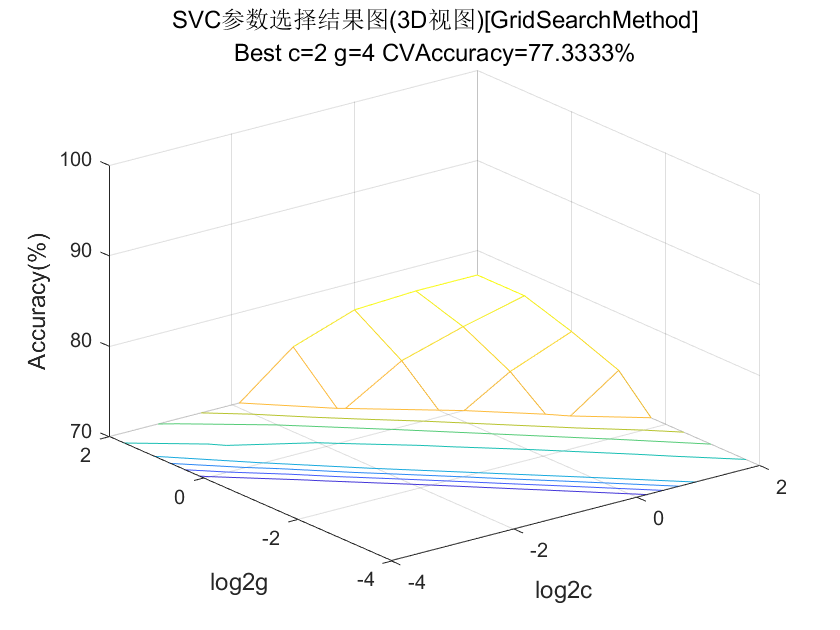

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 2.467165 秒。


*
optimization finished, #iter = 66
nu = 0.884058
obj = -110.102507, rho = 0.492925
nSV = 122, nBSV = 122
*
optimization finished, #iter = 38
nu = 0.425862
obj = -38.680012, rho = 0.106309
nSV = 60, nBSV = 58
*
optimization finished, #iter = 54
nu = 0.688741
obj = -65.495388, rho = 0.041032
nSV = 93, nBSV = 90
*
optimization finished, #iter = 52
nu = 0.419278
obj = -35.688831, rho = -0.074490
nSV = 60, nBSV = 56
*
optimization finished, #iter = 44
nu = 0.615316
obj = -56.204233, rho = -0.290021
nSV = 82, nBSV = 80
*
optimization finished, #iter = 65
nu = 0.881681
obj = -98.990696, rho = -0.242980
nSV = 120, nBSV = 118
Total nSV = 254
*
optimization finished, #iter = 61
nu = 0.865343
obj = -105.794972, rho = 0.316730
nSV = 118, nBSV = 116
*
optimization finished, #iter = 34
nu = 0.431272
obj = -38.969115, rho = 0.097028
nSV = 60, nBSV = 58
*
optimization finished, #iter = 52
nu = 0.695195
obj = -65.634265, rho = 0.068404
nSV = 93, nBSV = 90
*
optimization finished, #iter = 33
nu = 0.418

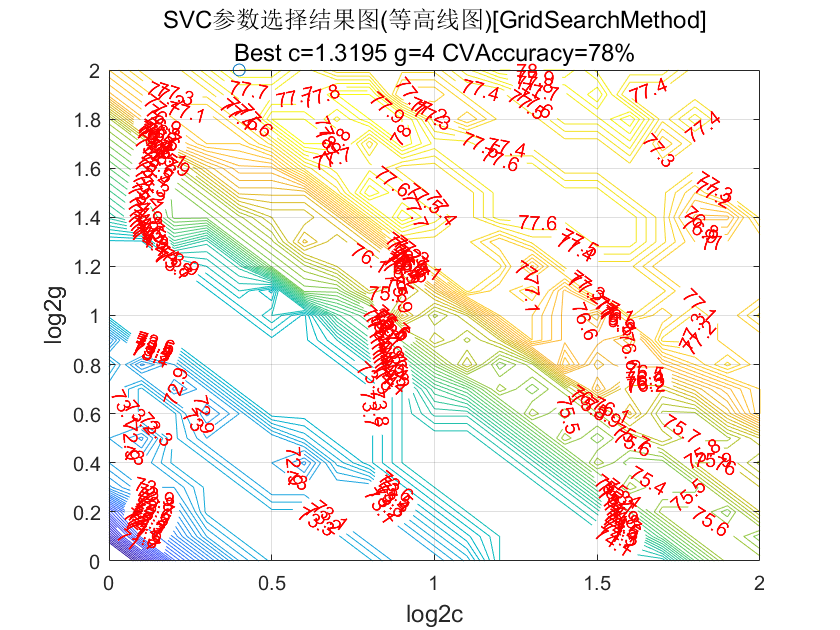

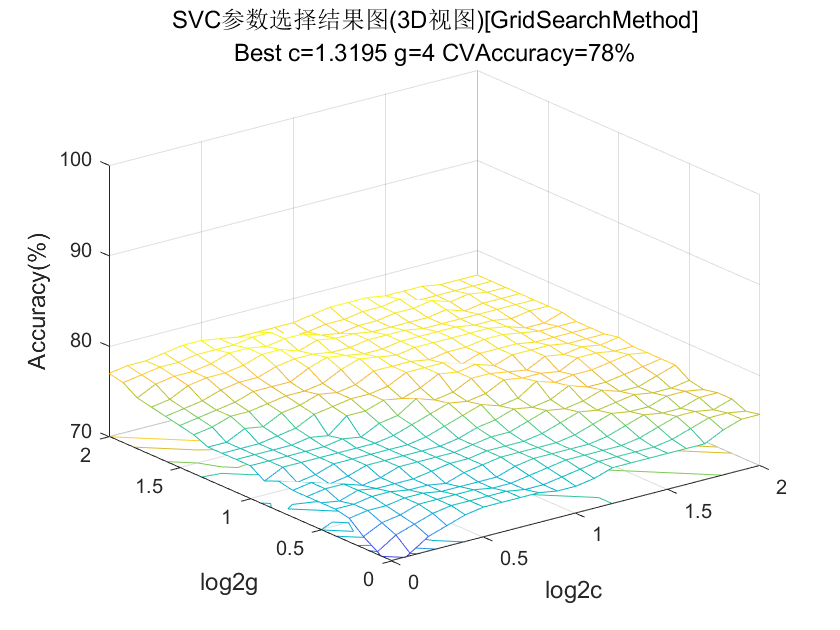

s = 0;
t = 0;
c = bestc;

g = bestg;

历时 18.816300 秒。


options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);
[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

*
optimization finished, #iter = 74
nu = 0.871029
obj = -240.926800, rho = 3.920230
nSV = 134, nBSV = 132
*
optimization finished, #iter = 34
nu = 0.392667
obj = -78.895071, rho = 3.199838
nSV = 62, nBSV = 59
*
optimization finished, #iter = 50
nu = 0.653061
obj = -137.832148, rho = 3.474706
nSV = 97, nBSV = 95
*
optimization finished, #iter = 31
nu = 0.380102
obj = -71.463583, rho = 2.438332
nSV = 60, nBSV = 57
*
optimization finished, #iter = 45
nu = 0.579950
obj = -117.818495, rho = 1.352635
nSV = 86, nBSV = 84
*
optimization finished, #iter = 70
nu = 0.882464
obj = -216.263676, rho = -5.479961
nSV = 132, nBSV = 130
Total nSV = 276


Accuracy = 70.6667% (212/300) (classification)


Accuracy = 77% (77/100) (classification)
